# Original Image

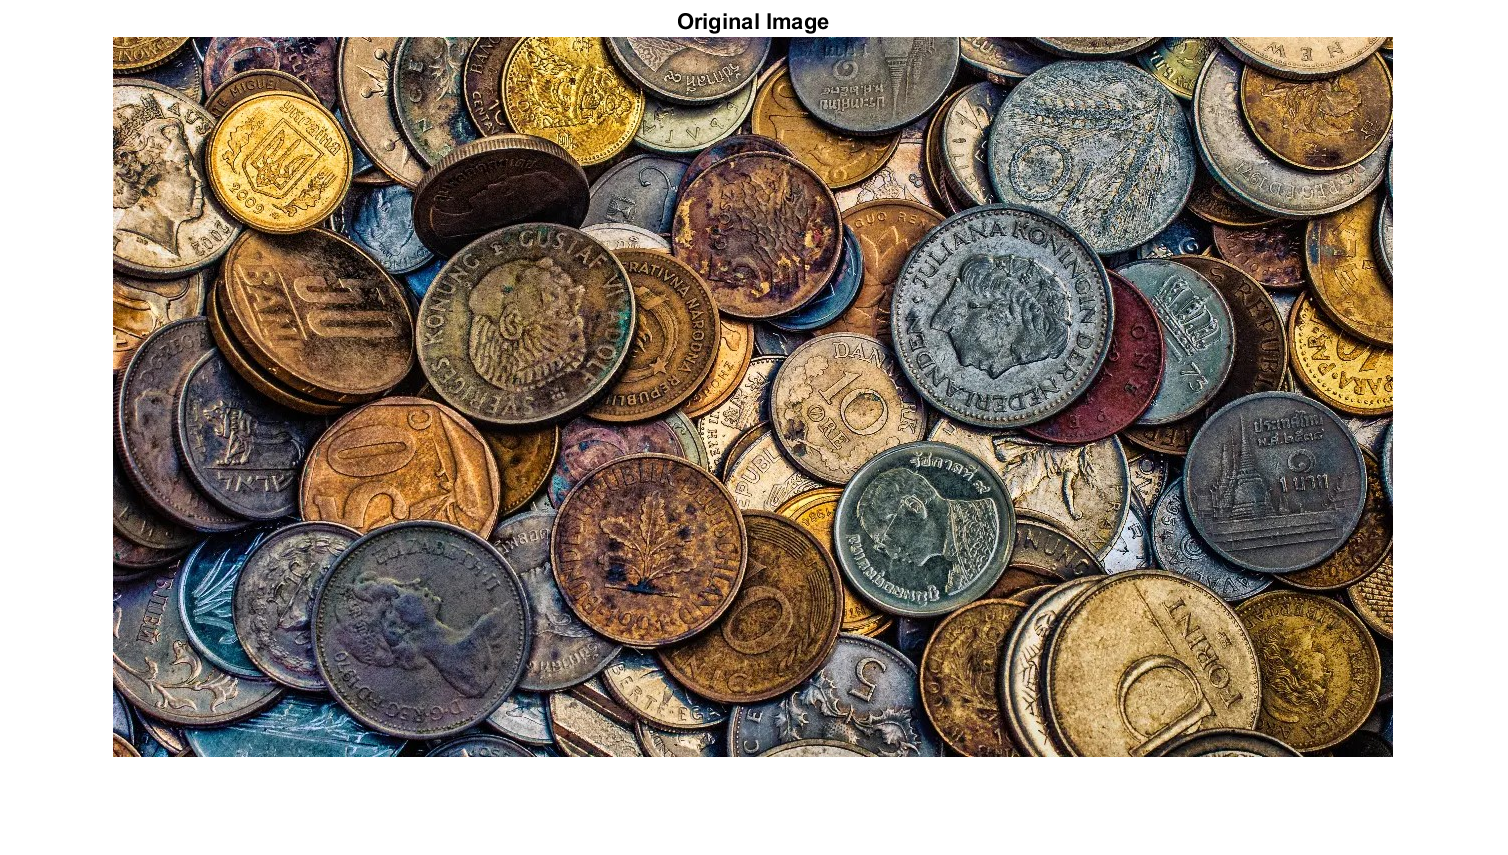

Image = imread('C:\Users\prana\OneDrive\Documents\MATLAB\coins.jpg');
imshow(Image)
title('Original Image');

## Add salt and pepper noise

Noise_level = input('How much noise do you want to add? (0 to 100%):');
Noisy_image = imnoise(Image, 'salt & pepper' ,Noise_level/100);

'imnoise' requires Image Processing Toolbox.

imshow(Noisy_image)
title('Corrupted with salt and pepper noise');

## Averaging filter

Output_avg = imfilter(Image, fspecial("average", Noise_level));
imshow(Output_avg)
title('Image filtered by Averaging filter');

## Median filter

Output_med = medfilt3(Noisy_image,[3 3 3]);
imshow(Output_med)
title('Image filtered by Median filter');

## Hue filter

hsvImage = rgb2hsv(Noisy_image);
hsvImage(:,:,1) = hsvImage(:,:,1) * 3;
rgbImage = hsv2rgb(hsvImage);
imshow(rgbImage)
title('Image filtered by Hue filter');

## **Gaussian filter**

Igauss = imgaussfilt3(Noisy_image,3);
imshow({Igauss})
title('Image filtered by Gaussian filter');